load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

HCV_array=table2array(HCV);

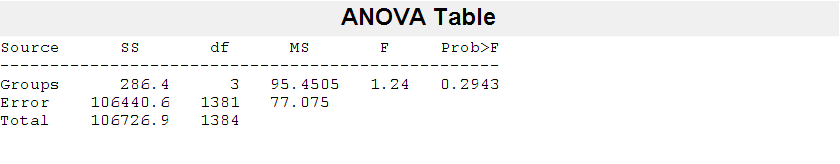

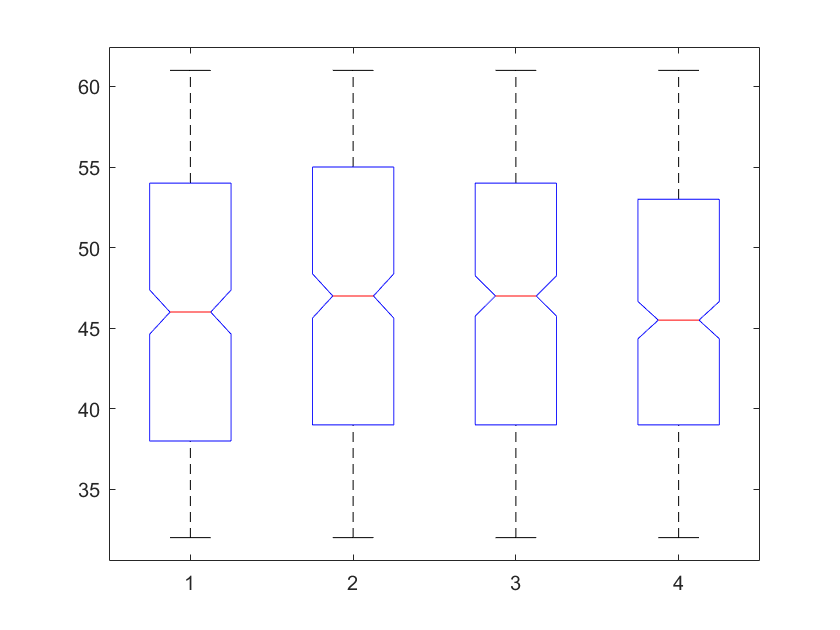

ans = 0.2943

%One way ANOVA
anova1(HCV.Age,HCV.Baselinehistologicalstaging)

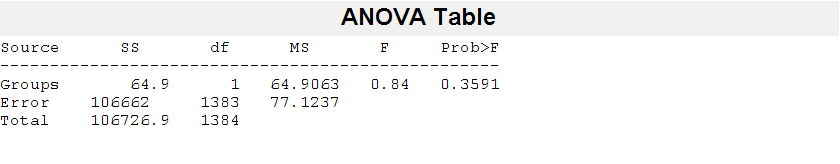

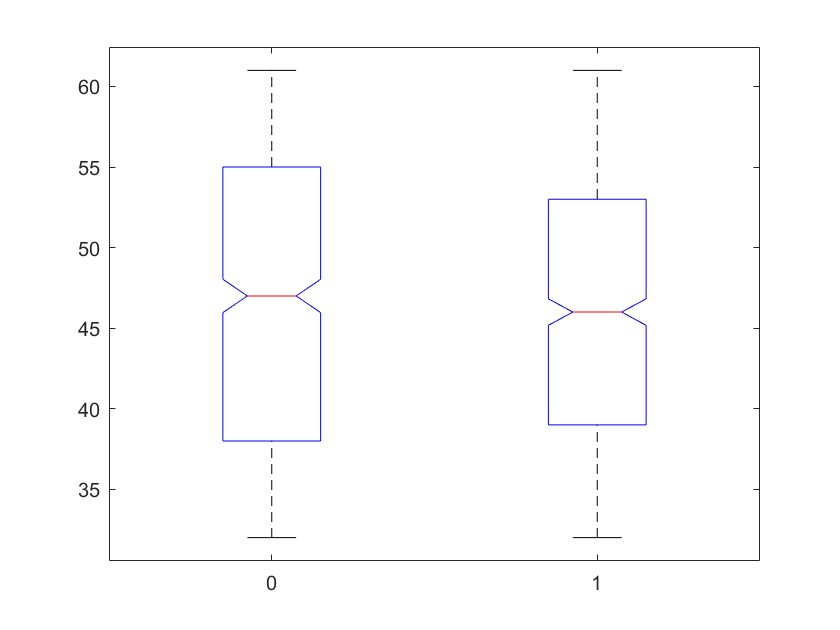

ans = 0.3591

anova1(HCV.Age,HCV.Baselinehistologicalstaging>2)

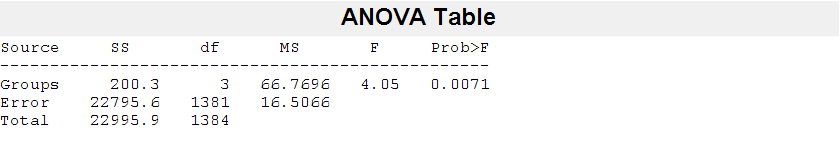

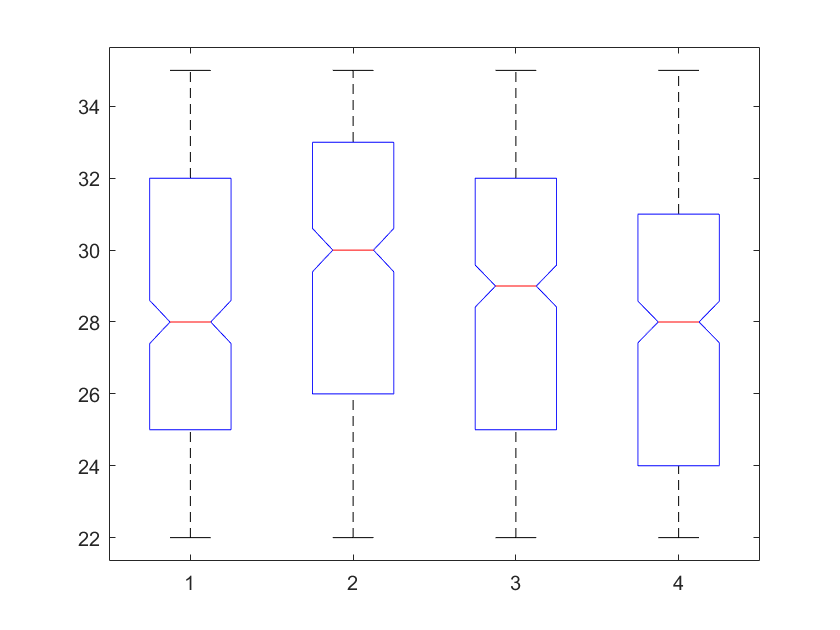

ans = 0.0071

% No age
anova1(HCV.BMI,HCV.Baselinehistologicalstaging)

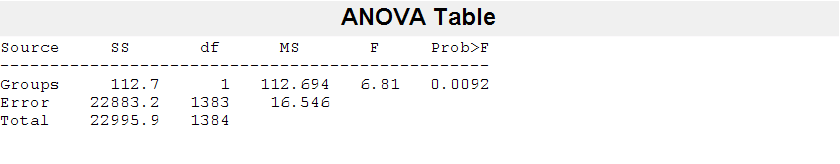

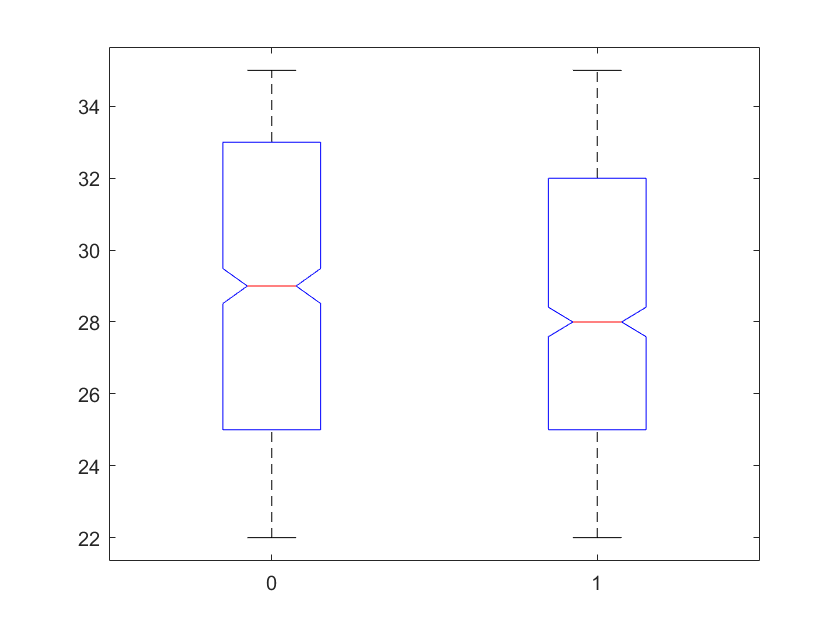

ans = 0.0092

anova1(HCV.BMI,HCV.Baselinehistologicalstaging>2)

% yes BMI
k=1;
for i=[1,3,11:27]
    a(k)=anova1(HCV.(i),HCV.Baselinehistologicalstaging,'off');
    b(k)=anova1(HCV.(i),HCV.Baselinehistologicalstaging>2,'off');
    k=k+1;
end
dat=array2table([a', b'],'RowNames',HCV.Properties.VariableNames([1,3,11:27]));

[b2,i2]=mink(b',2);
[b1,i1]=mink(a',2);

s2=find(b'<0.05);
s4=find(a'<0.05);

disp('Significant variables for 2 stages are')

Significant variables for 2 stages are


dat.Properties.RowNames(s2(1:end))

ans = 2×1 cell array
    {'BMI'  }
    {'RNAEF'}


disp('Significant variables for 4 stages are')

Significant variables for 4 stages are


dat.Properties.RowNames(s4(1:end))

ans = 1×1 cell array
    {'BMI'}


dat=sortrows(dat,'Var2')

dat = 19×2 table
                     Var1         Var2   
                   _________    _________

    BMI            0.0070928    0.0091578
    RNAEF            0.06269     0.039441
    ALTafter24w      0.43768      0.16479
    RNABase          0.39384      0.18344
    RNA4             0.51228      0.22876
    RNA12             0.5835      0.26798
    Age              0.29434       0.3591
    ALT1             0.45991      0.39287
    Plat              0.5931      0.44245
    AST1             0.48621      0.59874
    ALT48            0.65219      0.66032
    RNAEOT           0.86576      0.70201
    WBC              0.73046      0.75478
    ALT4             0.71518      0.76749
    

% Logistic regression - to understand association between categorical and continuous variables 
% Multinomial Logistic Regression
[B1, dev1,stats1] = mnrfit(HCV_array(:,1:27),HCV_array(:,29))

B1 =    -0.7005   -1.9582   -0.1212
    0.0057    0.0179    0.0105
    0.0450   -0.1275    0.2865
    0.0294    0.0677    0.0263
    0.2179    0.1522    0.1913
   -0.2406   -0.1803    0.0452
    0.0185   -0.0272   -0.0290
    0.0731   -0.1006   -0.0501
   -0.1433    0.0612   -0.1258
   -0.1536    0.1397   -0.0959


dev1 = 3.7568e+03

stats1 = struct with fields:
         beta: [28×3 double]
          dfe: 4071
         sfit: 1.0109
            s: 1
      estdisp: 0
         covb: [84×84 double]
    coeffcorr: [84×84 double]
           se: [28×3 double]
            t: [28×3 double]
            p: [28×3 double]
        resid: [1385×4 double]
       residp: [1385×4 double]
       residd: [1385×1 double]


stats1.p

ans =     0.6853    0.2640    0.9431
    0.5192    0.0433    0.2247
    0.7704    0.4136    0.0595
    0.1225    0.0005    0.1605
    0.1569    0.3268    0.2069
    0.1206    0.2486    0.7678
    0.9046    0.8613    0.8485
    0.6372    0.5201    0.7424
    0.3531    0.6943    0.4083
    0.3190    0.3698    0.5280


% Mod vs Adv :p(2) - Age, BMI

% Linear Regression
B2 = fitlm(HCV,"ResponseVar","Baselinehistologicalstaging",'CategoricalVars',{'BaselinehistologicalGrading','Diarrhea','Epigastricpain','Fatiguegeneralizedboneache','Fever','Gender','Headache','Jaundice','NauseaVomting'})

B2 = Linear regression model:
    Baselinehistologicalstaging ~ 1 + Age + Gender + BMI + Fever + NauseaVomting + Headache + Diarrhea + Fatiguegeneralizedboneache + Jaundice + Epigastricpain + WBC + RBC + HGB + Plat + AST1 + ALT1 + ALT4 + ALT12 + ALT24 + ALT36 + ALT48 + ALTafter24w + RNABase + RNA4 + RNA12 + RNAEOT + RNAEF + BaselinehistologicalGrading

Estimated Coefficients:
                                       Estimate          SE         tStat        pValue  
                                      ___________    __________    ________    __________

    (Intercept)                            3.0366       0.64264      4.7252    2.5397e-06
    Age                                -0.0034607     0.0034763    -0.99552       0.31966
    Gender_2                             0.027401      0.060968     0.449

% Get 2 x 2 table for categorical
%               Advanced Fibrosis
%               Yes         No
% Gender(Male)
% Gender(Female)
gen_stage=HCV(:,[2,29])

gen_stage = 1385×2 table
    Gender    Baselinehistologicalstaging
    ______    ___________________________

      1                    2             
      1                    2             
      1                    4             
      2                    3             
      1                    1             
      2                    4             
      2                    4             
      2                    3             
      1                    2             
      1                    2             
      2                    2             
      1                    1             
      2                    1             
      1                    2             
      2                    2             
      1                    1             


i11=sum(gen_stage.(1)==1 & (gen_stage.(2)==3 | gen_stage.(2)==4))

i11 = 352

i12=sum(gen_stage.(1)==1 & (gen_stage.(2)==1 | gen_stage.(2)==2))

i12 = 355

i21=sum(gen_stage.(1)==2 & (gen_stage.(2)==3 | gen_stage.(2)==4))

i21 = 365

i22=sum(gen_stage.(1)==2 & (gen_stage.(2)==1 | gen_stage.(2)==2))

i22 = 313

t=array2table([i11 i12;i21 i22],'RowNames',{'Present','Not Present'},'VariableNames',{'Present','Not Present'})

t = 2×2 table
                   Present    Not Present
                   _______    ___________

    Present          352          355    
    Not Present      365          313    


% Cramer's V
c=mestab([i11 i12;i21 i22])

c = struct with fields:
            baseRate: 0.5177
         sensitivity: 0.4909
         specificity: 0.4686
     posPredictValue: 0.4979
     negPredictValue: 0.4617
      riskDifference: -0.0405
    riskDifferenceCi: [-0.0931 0.0121]
           riskRatio: 0.9248
         riskRatioCi: [0.8354 1.0238]
           oddsRatio: 0.8503
         oddsRatioCi: [0.6885 1.0501]
                 phi: -0.0405
               phiCi: [-0.0969 NaN]
        successTreat: 0.4798
         successCtrl: 0.5202
                chi2: 2.2702


function stats=mestab(table,varargin)
% ** function stats=mestab(table,varargin) computes basal parameters and
% effect size measures from N by M tables of categorical outcomes (mostly 
% 2 by 2 tables) and according confidence intervals where applicable and
% possible. The exact analyses/parameters need not be specified; as the
% computations involved are trivial all parameters will be computed and
% placed in output variable stats. All input parameters except table are
% optional and must be specified as parameter/value pairs in any order,
% e.g. as in
%      mestab(table,'confLevel',.90)
%
%                           INPUT ARGUMENTS
%                           ---------------
% stats=mestab(table)  computes all implemented parameters and effect size 
%   measure(s) listed below in TABLE 1. table must be minimally a 2 by 2 
%   table of frequencies of occurrence with the following row and column 
%   order:
%                          CHARACTERISTIC 1
%                        | - PRESENT         - NOT PRESENT
%       ------------------------------------------------
%       CHARACTERISTIC 2 |      
%       - PRESENT        |
%       - NOT PRESENT    |
%
%                        or (as a specific example)
% 
%                        | TRUE POSITIVE     TRUE NEGATIVE
%       ------------------------------------------------
%       TEST POSITIVE    |
%       TEST NEGATIVE    |
% 
%   To give another example, the rows are the dichotomous values of the
%   independent variable (e.g. control and treatment group) and the columns
%   those of the dependent variable (e.g. outcome):
%
%                        | OUTCOME NEGATIVE  OUTCOME POSITIVE
%       ------------------------------------------------
%       CONTROL          |
%       TREATMENT        |
%
%   If table is larger than 2 by 2 the only parameter to be computed is
%   Cramer's V.
% stats=mestab(...,'confLevel',0.90)  computes 90 % confidence intervals of 
%   the statistic in question (95 % ci are the default)
%
%                         OUTPUT ARGUMENTS
%                         ----------------
%   The results of the computations are placed into fields of output
%   argument stats with names corresponding to the analyses listed in
%   TABLE 1, e.g. 
%     .riskDifference
%     .riskRatio
%     ...
%   Where applicable, confidence intervals will be placed in fields 
%     .riskDifferenceCi
%     .riskRatioCi
%     ...
% Additional output fields are:
%     .confLevel (confidence level)
% -------------------------------------------------------------------------
% TABLE 1: PARAMETERS COMPUTED
% -------------------------------------------------------------------------
% FIELD NAME           QUANTITIY COMPUTED, SYNONYMS
%        -- measures for 2 by 2 tables --
% riskDifference       risk difference, proportion difference
% riskRatio            risk ratio, rate ratio
% oddsRatio            odds ratio
% phi                  degree of association
% baseRate             base rate
% sensitivity          sensitivity
% specificity          specificity
% posPredictValue      positive predictive value
% negPredictValue      negative predictive value
% successTreat         binomial effect size display: success rate (treated)
% successCtrl          binomial effect size display: success rate (control)
%        -- measures for M by N tables --
% cramerV              Cramer's V
% -------------------------------------------------------------------------
% -------------------------------------------------------------------------
% Measures of Effect Size Toolbox Version 1.6.1, November 2018
% Code by Harald Hentschke (University Hospital of Tübingen) and 
% Maik Stüttgen (University Medical Center Mainz)
% For additional information see Hentschke and Stüttgen, 
% Eur J Neurosci 34:1887-1894, 2011
% -------------------------------------------------------------------------
% ----- default values & varargin -----
% standard values of optional input arguments
confLevel=.95;
% check variable number of input args:
% - even number (parameter AND value specified)?
% - convert to proper upper/lowercase spelling as above
% - check whether valid parameter was given
% - overwrite defaults by values, if specified
nvarg=numel(varargin);
v=who;
if nvarg
  if nvarg/2==round(nvarg/2)
    for g=1:2:nvarg
      % check which optional input parameter is given, ignoring case, and
      % impose spelling used internally
      ix=find(strcmp(lower(varargin{g}),lower(v)));
      if ~isempty(ix)
        varargin{g}=v{ix};
      else
        error(['invalid optional input parameter (' varargin{g} ') was specified']);
      end
    end
    % finally, the assignment of values to parameters
    pvpmod(varargin);
  else
    error('optional input parameters must be specified as parameter/value pairs, e.g. as in ''par1'',1')
  end
end
% -------------------------------------------------------------------------
% ------- PART I: CHECKS OF INPUT ARGS & OTHER PREPARATORY WORKS ----------
% -------------------------------------------------------------------------
alpha=1-confLevel;
% --- check input table
[nRow nCol]=size(table);
if nRow<2 || nCol<2
  error('table size must at least be 2 by 2');
end
% what kinda table?
if nRow==2 && nCol==2
  is2by2=true;
else
  is2by2=false;
end
% reject foul values
if any(any(~isfinite(table)))
  error('input variable table contains foul data (nan or inf))');
end
% --- check other input arguments
if confLevel<=0 || confLevel>=1
  error('input variable ''confLevel'' must be a scalar of value >0 and <1');
end
% -------------------------------------------------------------------------
% ------- PART II: THE WORKS ----------
% -------------------------------------------------------------------------
if is2by2
  % first, for convenience, assign entries in table to alphabetic letters
  % according to Kline 2004 (p. 146) (all lowercase, though).
  % note linear indexing of a 2D-var
  a=table(1);
  b=table(3);
  c=table(2);
  d=table(4);
  
  % compute basal parameters 
  stats.baseRate=(a+c)/(a+b+c+d);
  stats.sensitivity=a/(a+c);
  stats.specificity=d/(b+d);
  stats.posPredictValue=a/(a+b);
  stats.negPredictValue=d/(c+d);
  
  % now compute values based on proportions. As all computations involved
  % are trivial and variable sizes miniscule let's not worry about their
  % redundancy and proliferation, respectively, and use the same
  % nomenclature as Kline 2004
  p_c=a/(a+b);
  p_t=c/(c+d);
  % will be needed for confidence intervals
  z2tailFactor=norminv(alpha/2)*[1 -1];
  
  % risk difference  
  stats.riskDifference=p_c-p_t;
  % confidence intervals
  stats.riskDifferenceCi=stats.riskDifference + ...
    sqrt(p_c*(1-p_c)/(a+b) + p_t*(1-p_t)/(c+d)) * z2tailFactor;
  % risk ratio
  stats.riskRatio=p_c/p_t;
  % confidence intervals of risk ratio: for better readibility compute in
  % two steps
  tmp=log(stats.riskRatio) + ...
    sqrt((1-p_c)/((a+b)*p_c) + (1-p_t)/((c+d)*p_t)) * z2tailFactor;
  stats.riskRatioCi=exp(tmp);
  % odds ratio
  stats.oddsRatio=a*d/(b*c);
  % ci: same story 
  tmp=log(stats.oddsRatio) + ...
    sqrt( 1/((a+b)*p_c*(1-p_c)) + 1/((c+d)*p_t*(1-p_t))) * z2tailFactor;
  stats.oddsRatioCi=exp(tmp);
  % the measure of association termed phi [equivalent:
  % stats.phi=(a*d-b*c)/sqrt((a+b)*(c+d)*(a+c)*(b+d));]
    
  % ** use code for Cramer's V for confidence intervals
  [stats.phi stats.phiCi chi2]=cramerv(table,nRow,nCol,confLevel,is2by2);
  % finally, binomial effect size display (to quote Randolph & Edmondson
  % 2005, 'What would the correlationally equivalent effect of the
  % treatment be if 50% of the participants had the occurrence and 50% did
  % not and 50% received treatment and 50% did not?')
  stats.successTreat=.5+stats.phi/2;
  stats.successCtrl=.5-stats.phi/2;
else
  % the only thing to be computed here is Cramer's V (and chi2)
  [stats.cramerV stats.cramerVCi chi2]=cramerv(table,nRow,nCol,confLevel,is2by2);
end
% for the sake of being complete, add chi square to stats
stats.chi2=chi2;
% ========================= LOCAL FUNCTIONS ===============================
% ========================= LOCAL FUNCTIONS ===============================
function [es,esCi,chi2]=cramerv(table,nRow,nCol,confLevel,is2by2)
% this function computes Cramer's V, including exact analytical CI
% ** NOTE: in the case of 2 by 2 tables Cramer's V is identical to phi
% except possibly for the sign), which will be taken care of in the last
% lines
colSum=sum(table);
rowSum=sum(table,2);
n=sum(sum(table));
k=min(nRow,nCol);
df=(nRow-1)*(nCol-1);
% expected frequency of occurrence in each cell: product of row and
% column totals divided by total N
ef=(rowSum*colSum)/n;
% chi square stats
chi2=(table-ef).^2./ef;
chi2=sum(chi2(:));
% Cramer's V
es=sqrt(chi2/(n*(k-1)));
% CI (Smithson 2003, p. 40)
ncp=ncpci(chi2,'X2',df,'confLevel',confLevel);
esCi=sqrt((ncp+df)/(n*(k-1)));
% in case we are dealing with 2 by 2 tables heed sign
if is2by2
  if det(table)<0
    es=es*-1;
    esCi=fliplr(esCi)*-1;
  end
end
end
end

function ci=ncpci(x,fType,df,varargin)
%  ** function ci=ncpci(x,fType,df,varargin)
% iteratively approaches two-sided confidence intervals for the
% noncentrality parameter of a noncentral Chi square (abbreviated X2), F or
% t distribution with degrees of freedom df, given an abscissa value (X2, F
% or t value). This is achieved by varying the X2, F or t noncentrality
% parameter of the corresponding probability distribution function (pdf)
% until the given abscissa value is, within a certain precision, at the
% percentile values required for the confidence interval (2.5th and 97.5th
% percentile for lower and upper 95 % confidence intervals, respectively).
% All input parameters listed below except x, fType and df are
% optional and must be specified as parameter/value pairs, e.g. as in
%          ncpci(x,'t',df,'confLevel',.9)
%
%               >>> INPUT VARIABLES >>>
% NAME          TYPE/DEFAULT      DESCRIPTION
% x             double scalar     X2, F or t value
% fType         char              'X2','F' or 't'
% df            scalar or array   degrees of freedom 
%                                 (F pdf: [numerator denominator])
% confLevel     double, 0.95      confidence level
% prec          double scalar,    precision: iteration will run until the
%                1e-6             estimated percentile is <=prec away from
%                                 the requested percentile
% doAnimate     logical,false     if true, the iteration process will be
%                                 graphically displayed in a figure window
%                     
%               <<< OUTPUT VARIABLES <<<
% NAME          TYPE/DEFAULT           DESCRIPTION
% ci            2 element array        confidence intervals
% -------------------------------------------------------------------------
% Measures of Effect Size Toolbox Version 1.6.1, November 2018
% Code by Harald Hentschke (University Hospital of Tübingen) and 
% Maik Stüttgen (University Medical Center Mainz)
% For additional information see Hentschke and Stüttgen, 
% Eur J Neurosci 34:1887-1894, 2011
% -------------------------------------------------------------------------
% defaults
prec=1e-6;
confLevel=.95;
doAnimate=false;
% replace defaults by input, if any
pvpmod(varargin);
% convert df to cell for automatic expansion of parameters
df=num2cell(df);
% convert confidence level to alpha
alpha=1-confLevel;
% target p values 
pTarget=[1-alpha/2  alpha/2];
% --- error checks, assignments of function handles, etc.
% are we dealing with pdf defined only for positive abscissa values?
isPosPdf=ismember(fType,{'X2','F'});
% if so...
if isPosPdf && x<0
  error('input arg ''x'' is negative but must be positive for X2 and F distributions')
end
% start index for outermost loop below, determining whether lower CI shall
% be computed or not
loopStartIx=1;
switch fType
  case 'X2'
    curPdf=@ncx2pdf;    
    curCdf=@ncx2cdf;
    curInv=@chi2inv;
    % abscissa limits for plots (if doAnimate==true): first row for lower
    % CI, second row for upper CI
    abscissLim=[0 2*x;0 5*x];
    % check: if cdf of x with noncentrality parameter 0 is less than
    % 1-alpha/2 don't even start on the lower CI because the iteration will
    % not converge (that is, there is no lower CI for given values of x and
    % df)
    if chi2cdf(x,df{:})<1-alpha/2
      % lower CI cannot be constructed as it is too close to zero - set to
      % NaN
      ci=nan;
      loopStartIx=2;
    end
    
  case 'F'
    curPdf=@ncfpdf;    
    curCdf=@ncfcdf;
    curInv=@finv;
    abscissLim=[0 2*x;0 5*x];
    % similar check as above
    if fcdf(x,df{:})<1-alpha/2
      % lower CI cannot be constructed as it is too close to zero - set to
      % NaN
      ci=nan;
      loopStartIx=2;
    end
    
  case 't'
    curPdf=@nctpdf;
    curCdf=@nctcdf;
    curInv=@tinv;
    abscissLim=x+[-4 2;-2 4]*sqrt(abs(x));
    
  otherwise
    error('illegal distribution function specified');
end
if prec>.001
  warning('results will be inaccurate - set input parameter ''prec'' to a lower value');
end
if doAnimate
  fh=figure;
  ph0=plot(x,0,'k^');
  hold on
  set(ph0,'markerfacecolor','k','markersize',6);
  ph=[];
  ti={'lower CI','upper CI'};
end
% loop twice: first lower ci (but see above), then upper ci
for iIx=loopStartIx:2
  % determine initial values: there are probably better ways of estimating
  % the limits of ncp for X2 and F pdfs than the guesses below (which work
  % best if the X2/F/t value is small)
  switch fType
    case 'X2'
      if iIx==1
        % lower CI
        ncp=x+curInv(pTarget(iIx),df{:});
      else
        % upper CI
        ncp=5*x;
      end
      
    case 'F'
      if iIx==1
        ncp=x+curInv(pTarget(iIx),df{:});
      else
        ncp=10*x;
      end
      
    case 't'
      % as a rough first approximation, assume that lower/upper limit of
      % ncp is close to corresponding percentiles of central pdfs
      if iIx==1
        ncp=x+curInv(pTarget(iIx),df{:});
      else
        ncp=x-curInv(pTarget(iIx),df{:});
      end
  end
  
  % interval of first estimates: guessed ncp enlarged by x/2 on either side
  ncp=ncp+abs(x)*[-.5 .5];
  % p values of current estimates
  p=curCdf(x,df{:},ncp);
  % deviations of p of current noncentral x pdfs from target p value
  deltaP=p-pTarget(iIx);
  nIter=1;
  if doAnimate
    ph=plotPdf(x,ncp,ph,curPdf,df,iIx,nIter,abscissLim,ti);
  end
  % while desired precision is not reached...
  while ~any(abs(deltaP)<=prec)
    if all(deltaP>0)
      % shift interval to the right by one interval length
      ncp=[ncp(2) ncp(2)+abs(diff(ncp))];
    elseif all(deltaP<0)
      % shift left by one interval length
      ncp=[ncp(1)-abs(diff(ncp)) ncp(1)];
    else
      % halve interval around mean
      ncp=mean(ncp)+.25*abs(diff(ncp))*[-1 1];
    end
    % X2 and F distributions need an extra check: the lower ncp must be >=0
    if isPosPdf
      if ncp(1)<0
        ncp(1)=0;
      end
      % if both values of ncp are zero here the upper CI is zero, too, so
      % stop here
      if ~any(ncp)
        break
      end
    end
    % p values of current estimates
    p=curCdf(x,df{:},ncp);
    % deviations of p of current nc x pdfs from target
    deltaP=p-pTarget(iIx);
    nIter=nIter+1;
    if doAnimate
      ph=plotPdf(x,ncp,ph,curPdf,df,iIx,nIter,abscissLim,ti);
    end
  end
  % pick border which is closer to the target value
  [~,ix]=min(abs(deltaP));
  ci(iIx)=ncp(ix);
end
% close figure
if doAnimate
  pause(1)
  close(fh)
end
% ======================== LOCAL FUNCTION =================================
function ph=plotPdf(x,ncp,ph,pdfH,df,iIx,nIter,abscissLim,ti)
% ** function ph=plotPdf(x,ncp,ph,pdfH,df,iIx,nIter,abscissLim,ti)
% If doAnimate==true, plotPdf plots x (first input arg to ncpci) and
% noncentral pdfs with the noncentrality parameter estimates of each
% iteration step 
abscissVal=linspace(abscissLim(iIx,1),abscissLim(iIx,2),200);
if isempty(ph)
  ph(1)=plot(abscissVal,pdfH(abscissVal,df{:},ncp(1)),'-');
  ph(2)=plot(abscissVal,pdfH(abscissVal,df{:},ncp(2)),'-');
  set(ph(1),'color',[.9 .3 .3]);
  set(ph(2),'color',[.3 .3 .9]);
else
  set(ph(1),'xdata',abscissVal,'ydata',pdfH(abscissVal,df{:},ncp(1)));
  set(ph(2),'xdata',abscissVal,'ydata',pdfH(abscissVal,df{:},ncp(2)));  
end
title([ti{iIx} ', iteration # ' int2str(nIter)])
% supposedly, in animation mode we would like to be able to follow the
% iterative process with our eyes, so slow things down
drawnow
pause(.1)
end
end

function pvpmod(x,parNames)
% PVPMOD - evaluate parameter/value pairs
% pvpmod(x,parNames) assigns the value x(i+1) to the parameter defined by
% the string x(i) in the calling workspace. This is useful to evaluate
% <varargin> contents in an mfile, e.g. to change default settings of any
% variable initialized before pvpmod(x) is called. 
% Before these assignments the code checks whether the inputs are arranged
% in pairs with the first element of each pair being a char or string. If
% optional input argument parNames (a cell array of char arrays) is
% specified, it also ensures that each of the parameter names in x
% are part of the allowable set given in parNames.
% (c) U. Egert 1998
% Modified by H. Hentschke 2017
% new:
% 0. check inputs
if nargin>1
  validateattributes(parNames,{'cell'},{'nonempty'});
end
if ~isempty(x)
  % 0. check inputs
  validateattributes(x,{'cell'},{'nonempty'});
  % 1. check that we're really dealing with pairs in x (i.e. varargin has
  % an even number of elements)
  if rem(numel(x),2)~=0
    error('expecting parameter/value pairs')
  end
  for k = 1:2:numel(x)
    % 2. make sure the first input within a pair is a char or string
    validateattributes(x{k},{'char','string'},{'nonempty'});
    if nargin>1
      % 3. make sure strings match
      validatestring(x{k},parNames);
    end
    % now make assignments
    assignin('caller', x{k}, x{k+1});
  end
end
end